# CSS/BPSK変復調システム（Communication Toolbox 利用）

前提条件

- AWGN通信路

- SN比: 0dB

- 帯域幅: 250kHz

- 搬送波周波数: 1MHz

- サンプリング周波数: 20MHz

- ビットレート: 1kHz

- チップレート: 250kHz

## ワークスペースの初期化

clear
close all
clc
format long

## 図のフォント設定

set(0, 'defaultAxesFontSize', 14);
set(0, 'defaultAxesFontName', 'times');
set(0, 'defaultTextFontSize', 14);
set(0, 'defaultTextFontName', 'times');

## パラメータの設定

CARRIER_FREQ = 1e6;
MULTIPLE_LEVEL = 2;

BANDWIDTH = 250e3;

chipRate = BANDWIDTH;
chipPeriod = 1/chipRate;

snRatio = 0;

samplingFreq = 20*CARRIER_FREQ;
samplingPeriod = 1/samplingFreq;

bitRate = 1e3;
bitPeriod = 1/bitRate;
symbolRate = bitRate;
symbolPeriod = 1/symbolRate;

bitsPerSymbol = log2(MULTIPLE_LEVEL);

filterSpan = 6;
samplesPerSymbol = floor(symbolPeriod/samplingPeriod);
filterDA = rcosdesign(0.5, filterSpan, samplesPerSymbol, 'sqrt');
filterDelay = mean(grpdelay(filterDA))*((samplesPerSymbol-filterSpan/2)/samplesPerSymbol);

t = 0:1/samplingFreq:symbolPeriod-1/samplingFreq;

## 入力ビット列の確認

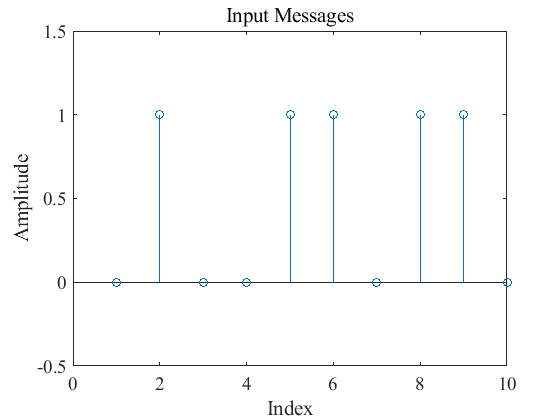

messages = [0 1 0 0 1 1 0 1 1 0];

stem(messages)
ylim([-0.5 1.5])
title('Input Messages')
xlabel('Index')
ylabel('Amplitude')

## 変調シンボル列の確認

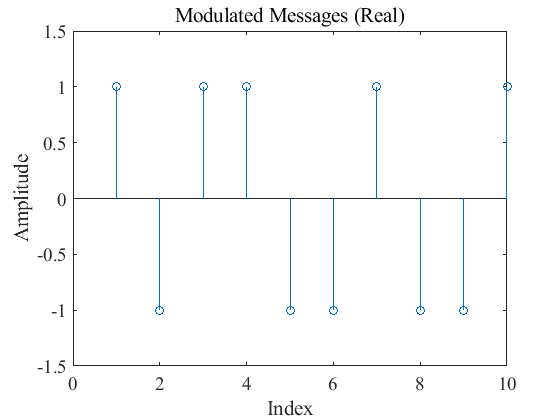

infoBinary = messages';
infoDecimal = bi2de(infoBinary, 'left-msb');
infoModulated = pskmod(infoDecimal, MULTIPLE_LEVEL, 0, 'gray');

stem(real(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

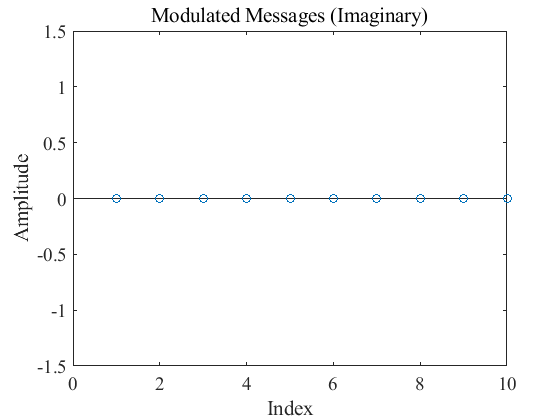

stem(imag(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## チャープ信号の確認

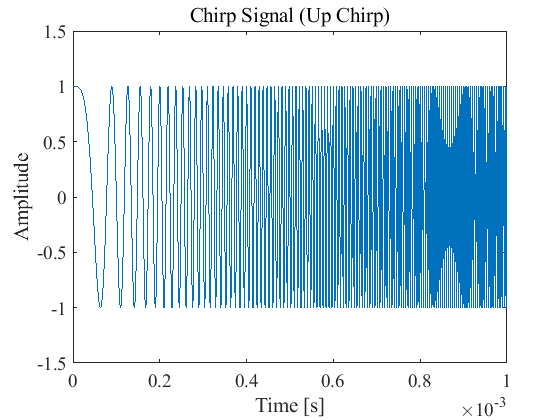

chirpUp = chirp(t, 0, symbolPeriod, chipRate);
chirpDown = chirp(t, chipRate, symbolPeriod, 0);

plot(t, chirpUp)
ylim([-1.5 1.5])
title('Chirp Signal (Up Chirp)')
xlabel('Time [s]')
ylabel('Amplitude')

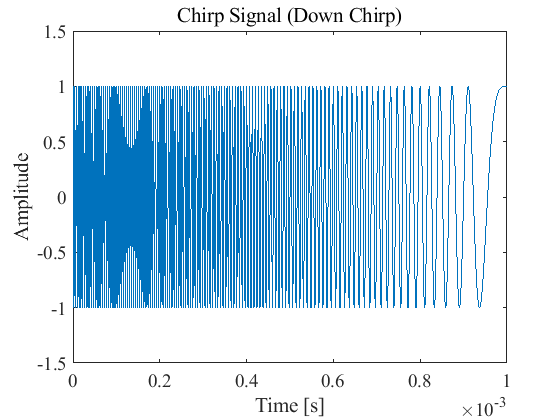

plot(t, chirpDown)
ylim([-1.5 1.5])
title('Chirp Signal (Down Chirp)')
xlabel('Time [s]')
ylabel('Amplitude')

## CSS信号の確認

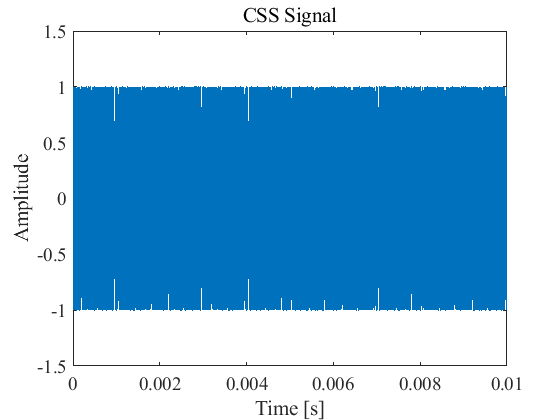

tt = 0:1/samplingFreq:length(infoModulated)*symbolPeriod-1/samplingFreq;

cssModulated = zeros(1, size(infoModulated,1)*size(t,2));
for k = 1:length(infoModulated)
    if real(infoModulated(k)) == -1
        cssModulated(1+(k-1)*size(t,2):k*size(t,2)) = chirpUp;
    elseif real(infoModulated(k)) == 1
        cssModulated(1+(k-1)*size(t,2):k*size(t,2)) = chirpDown;
    end
end

cssSignalTilde = cssModulated.*exp(1i*2*pi*CARRIER_FREQ*tt);

cssSignal = real(cssSignalTilde);

plot(tt, cssSignal)
ylim([-1.5 1.5])
title('CSS Signal')
xlabel('Time [s]')
ylabel('Amplitude')

## 雑音印加後の信号確認

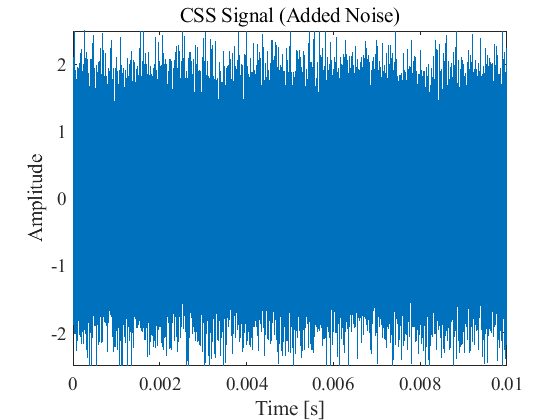

rng('shuffle')
signalAddedNoise = awgn(cssSignal, snRatio, 'measured');  % signalAddedNoise = cssSignal;

plot(tt, signalAddedNoise)
ylim([-2.5 2.5])
title('CSS Signal (Added Noise)')
xlabel('Time [s]')
ylabel('Amplitude')

## 出力ビット列の確認

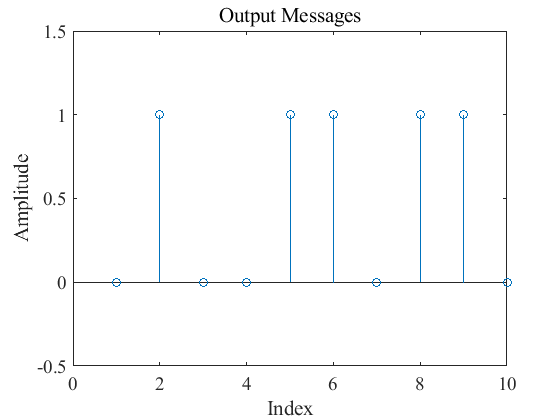

signalInverse = signalAddedNoise.*exp(-1i*2*pi*CARRIER_FREQ*tt);

z1 = zeros(1, size(infoDecimal,1));
z0 = zeros(1, size(infoDecimal,1));
for k = 1:length(infoDecimal)
    z1(k) = sum(signalInverse(1+(k-1)*size(t,2):k*size(t,2)).*chirpUp)*(2/(symbolPeriod*samplingFreq));
    z0(k) = sum(signalInverse(1+(k-1)*size(t,2):k*size(t,2)).*chirpDown)*(2/(symbolPeriod*samplingFreq));
end

receivedInfoBinary = zeros(1, size(infoBinary,1));
for k = 1:length(infoBinary)
    if real(z1(k)) >= real(z0(k))
        receivedInfoBinary(k) = 1;
    elseif real(z1(k)) < real(z0(k))
        receivedInfoBinary(k) = 0;
    end
end

recievedMessagesTilde = receivedInfoBinary';
recievedMessages = recievedMessagesTilde(:)';

stem(recievedMessages)
ylim([-0.5 1.5])
title('Output Messages')
xlabel('Index')
ylabel('Amplitude')

## ビット誤り率の確認

bitErrorRate = biterr(messages, recievedMessages)/length(messages)

bitErrorRate =      0
